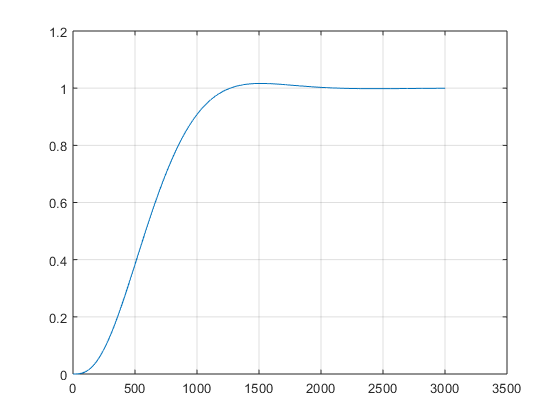

clean
t0 = 0;
tf = 1;
D = tf - t0;
ts = 1e-3;

x = 0;
v = 0;
a = 0;
j = 0;
f = 1;

log = [];

for t = 0:ts:3
    j = -60/D^3 * x + ...
        -36/D^2 * v + ...
        -09/D^1 * a + ...
        +60/D^3 * f;
    x = x + v * ts;
    v = v + a * ts;
    a = a + j * ts;
    log = [log x];
end
plot(log); grid;

disp([j a v x]);

   -0.0010   -0.0060    0.0021    0.9997



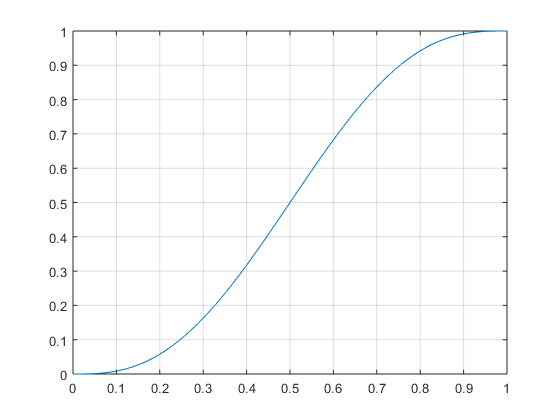

xi = 0; xf = 1; d = 1; ts = 1e-3;
t = 0:ts:d;
% x = xi + (xf - xi) * (10*(t/d).^3 - 15*(t/d).^4 + 6*(t/d).^5);
x = 10 * t.^3 - 15 * t.^4 + 6 * t.^5;
plot(t, x); grid;